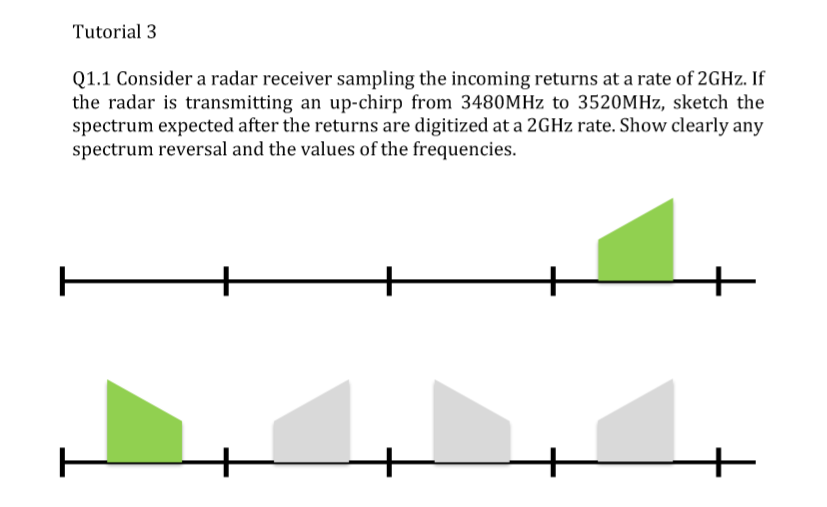

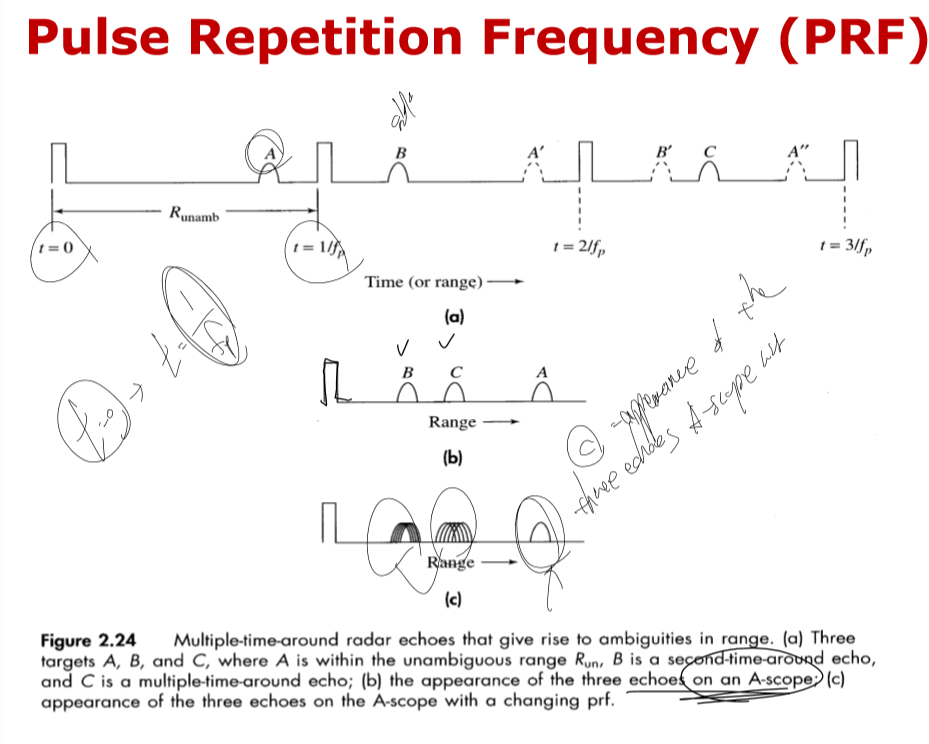

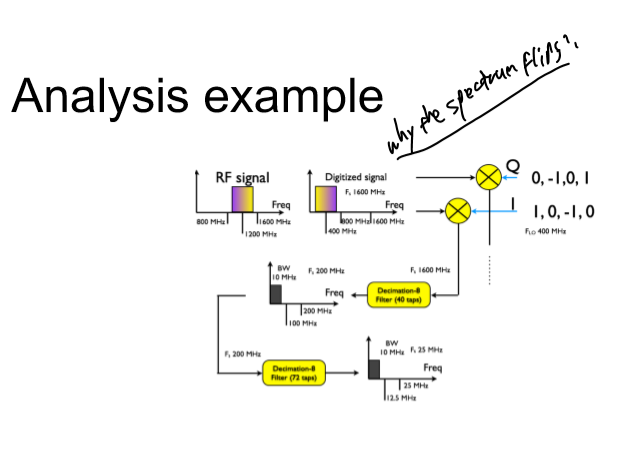

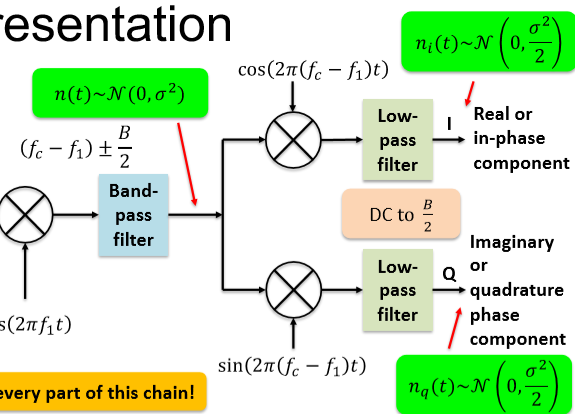

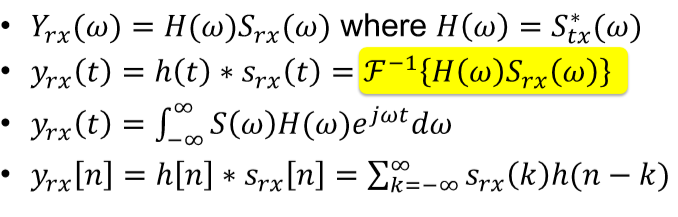

prove that 

Fs = 100;
t = 0: 1/Fs : 100*(1/Fs);
stx = sin(2*pi*10*t.^2);
fstx = fft(stx);
%plot(stx);
%rstx = stx(end:-1:1);
%plot(rstx); frstx = fft(rstx);
%plot(abs(fstx))
frstx

frstx =    7.2177 + 0.0000i   5.5910 + 5.3191i   0.0678 + 9.0863i  -8.4206 + 6.8081i -11.0483 - 4.4935i   1.9583 -11.2205i   9.5300 + 4.3350i  -9.5758 + 6.7025i   0.8012 -11.1667i   2.6630 +10.5391i  -6.0034 -10.0189i   2.5086 +10.5559i   0.5095 -11.1322i -10.0721 + 6.7446i   8.8209 + 4.4606i   1.0233 -11.0378i -12.3584 - 4.2173i -10.2551 + 7.3670i  -2.4004 +10.2491i   2.4685 + 7.6543i   3.8501 + 4.4704i   3.6036 + 2.3463i   2.9539 + 1.1972i   2.3523 + 0.6233i   1.8913 + 0.3402i   1.5547 + 0.1969i   1.3088 + 0.1209i   1.1257 + 0.0784i   0.9863 + 0.0534i   0.8777 + 0.0379i   0.7913 + 0.0278i   0.7213 + 0.0210i   0.6637 + 0.0163i   0.6158 + 0.0129i   0.5756 + 0.0104i   0.5415 + 0.0085i   0.5123 + 0.0070i   0.4874 + 0.0059i   0.4659 + 0.0049i   0.4473 + 0.0042i   0.4313 + 0.0035i   0.4176 + 0.0030i   0.4058 + 0.0025i   0.3957 + 0.0021i   0.3872 + 0.0018i   0.3802 + 0.0014i   0.3744 + 0.0011i   0.3700 + 0.0009i   0.3666 + 0.0006i   0.3645 + 0.0004i


cstx = conv(stx,rstx)

cstx =          0   -0.0000   -0.0060   -0.0277   -0.0655   -0.1099   -0.1534   -0.1999   -0.2590   -0.3330   -0.4125   -0.4850   -0.5464   -0.6017   -0.6548   -0.6991   -0.7185   -0.6990   -0.6376   -0.5411   -0.4172   -0.2673   -0.0883    0.1175    0.3343    0.5328    0.6797    0.7495    0.7304    0.6237    0.4388    0.1904   -0.0988   -0.3935   -0.6441   -0.7938   -0.7936   -0.6215   -0.2970    0.1152    0.5161    0.7973    0.8712    0.7008    0.3185   -0.1741   -0.6281   -0.8897   -0.8529   -0.5063


%plot(cstx)
%plot(abs(fft(cstx)))


The result proves that the bandwidth of the matched filter corresponds to the transmitted bandwidth

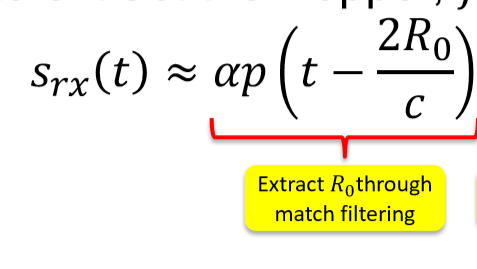v

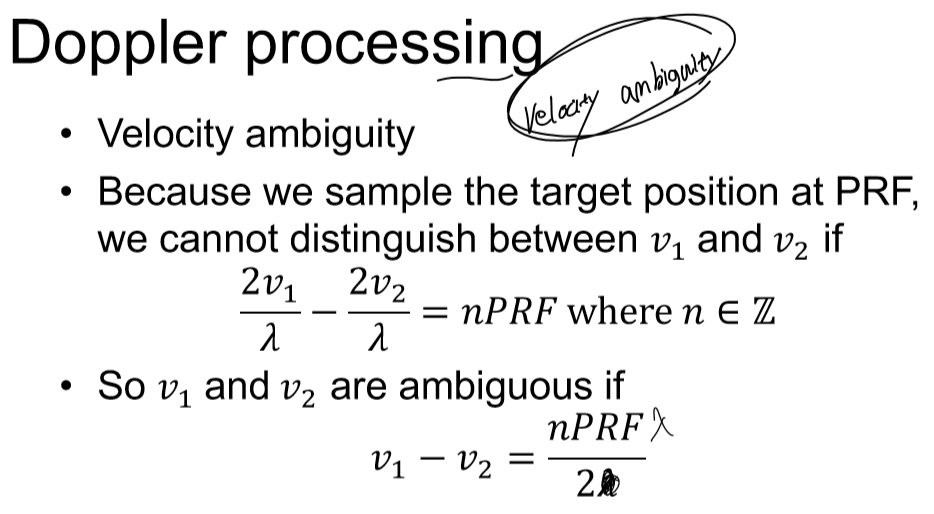

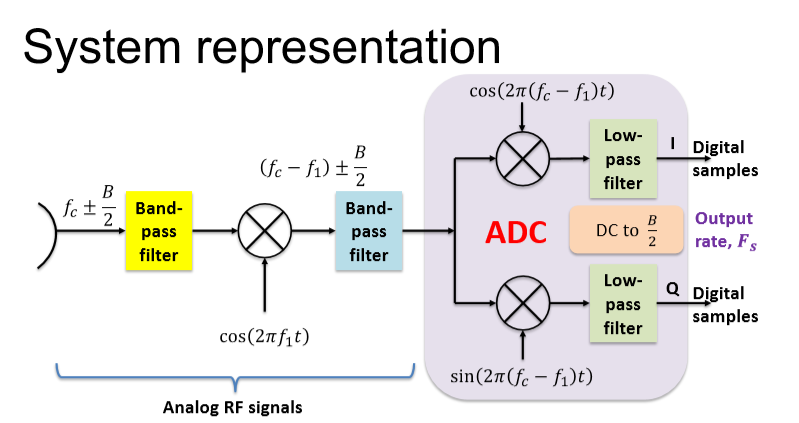

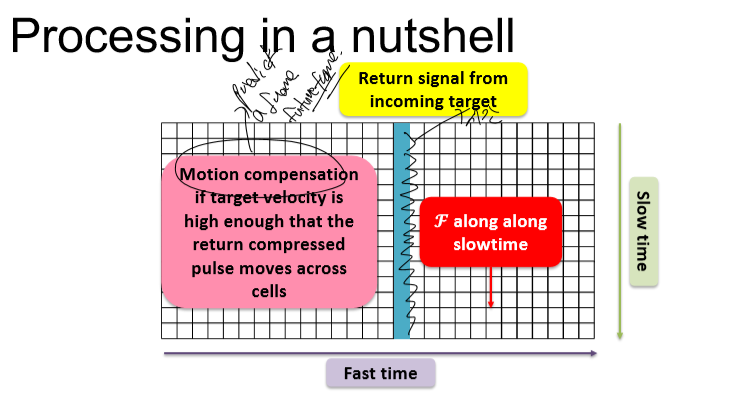

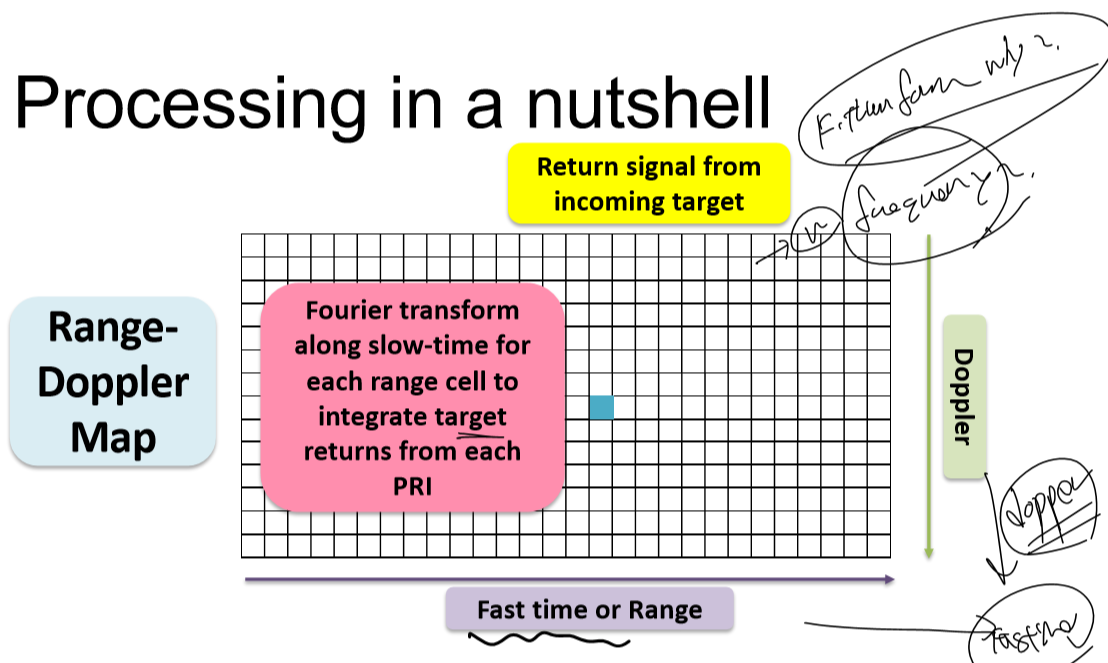

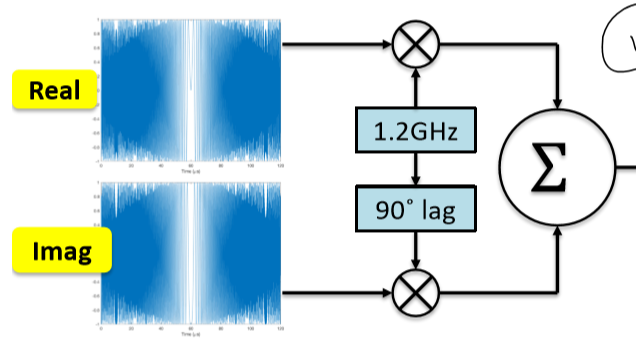

syms d theta r lambda;

for i = 0: 9
    sum = sum +  exp(j*2*pi*i*d*sin(theta)/lambda);
end
sum = sum.*exp(j*2*pi*1000/lambda);
sum = matlabFunction(sum)

sum = 다음 값을 갖는 function_handle :
    @(d,lambda,theta)exp((pi.*2.0e3i)./lambda).*(exp((d.*pi.*sin(theta).*2.0i)./lambda)+exp((d.*pi.*sin(theta).*4.0i)./lambda)+exp((d.*pi.*sin(theta).*6.0i)./lambda)+exp((d.*pi.*sin(theta).*8.0i)./lambda)+exp((d.*pi.*sin(theta).*1.0e1i)./lambda)+exp((d.*pi.*sin(theta).*1.2e1i)./lambda)+exp((d.*pi.*sin(theta).*1.4e1i)./lambda)+exp((d.*pi.*sin(theta).*1.6e1i)./lambda)+exp((d.*pi.*sin(theta).*1.8e1i)./lambda)+exp((pi.*2.0e3i)./lambda).*(exp((d.*pi.*sin(theta).*2.0i)./lambda)+exp((d.*pi.*sin(theta).*4.0i)./lambda)+exp((d.*pi.*sin(theta).*6.0i)./lambda)+exp((d.*pi.*sin(theta).*8.0i)./lambda)+exp((d.*pi.*sin(theta).*1.0e1i)./lambda)+exp((d.*pi.*sin(theta).*1.2e1i)./lambda)+exp((d.*pi.*sin(theta).*1.4e1i)./lambda)+exp((d.*pi.*sin(theta).*1.6e1i)./lambda)+exp((d.*pi.*sin(theta).*1.8e1i)./lambda)+exp((pi.*2.0e3i)./lambda).*(exp((d.*pi.*sin(theta).*2.0i)./lambda)+exp((d.*pi.*sin(theta).*4.0i)./lambda)+exp((d.*pi.*sin(theta).*6.0i)./lambda)+exp((d.*pi.*sin(theta).

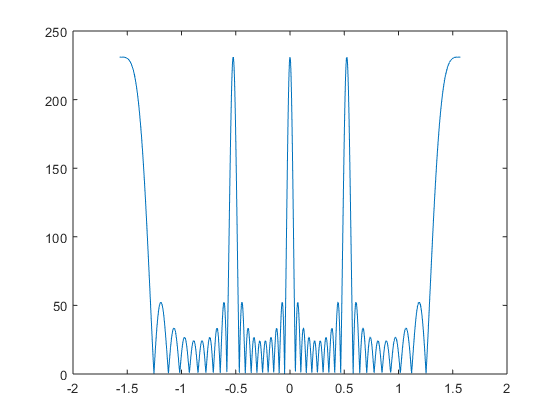

 
a = sum(200,100,[-pi/2:0.001:pi/2]);
%plot([-pi/2:0.001:pi/2],abs(a))

tan(0.1)

ans = 0.1003